% Paso 1: Pedir los valores de los puntos
n = input('Número de puntos: '); % Número de puntos

X = zeros(n, 1); % Inicializar vector de X
Y = zeros(n, 1); % Inicializar vector de Y

for i = 1:n
    X(i) = input(['X(' num2str(i) '): ']);
    Y(i) = input(['Y(' num2str(i) '): ']);
end

% Paso 2: Construir la matriz A y el vector Y
A = [ones(n, 1), X]; % Matriz A con columna de unos y valores de X
Y = Y; % Vector columna de valores Y

% Paso 3: Calcular la fórmula de ajuste
At = A'; % Transpuesta de A
AtA = At * A; % A' * A
AtA_inv = inv(AtA); % Inversa de (A' * A)
AtY = At * Y; % A' * Y
u = AtA_inv * AtY; % Coeficientes de la recta

% Mostrar los resultados
disp('Coeficientes de la recta:');

Coeficientes de la recta:


disp(['Intercepto (b): ' num2str(u(1))]);

Intercepto (b): 3.5714


disp(['Pendiente (m): ' num2str(u(2))]);

Pendiente (m): -0.88095



% Evaluar Y_hat para el modelo lineal
Y_hat_lineal = u(1) + u(2) * X;

% ---------- CÁLCULO DEL ERROR CUADRÁTICO MEDIO (ECM) ----------

% ECM para el modelo lineal
ECM_lineal = sum((Y - Y_hat_lineal).^2) / n;

% Mostrar el error cuadrático medio
disp(['Error Cuadrático Medio (ECM) - Modelo Lineal: ' num2str(ECM_lineal)]);

Error Cuadrático Medio (ECM) - Modelo Lineal: 1.6131


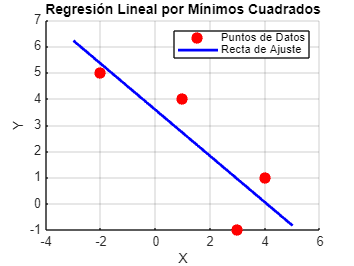


% ---------- GRAFICAR LOS RESULTADOS ----------

% Crear la gráfica
figure;
hold on;
grid on;

% Graficar los puntos de datos
plot(X, Y, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r', 'DisplayName', 'Puntos de Datos');

% Graficar la recta de ajuste
x_vals = linspace(min(X) - 1, max(X) + 1, 100); % Intervalo de la gráfica
y_vals = u(1) + u(2) * x_vals; % Valores de Y para la recta de ajuste
plot(x_vals, y_vals, 'b-', 'LineWidth', 2, 'DisplayName', 'Recta de Ajuste');

% Añadir etiquetas y título
xlabel('X');
ylabel('Y');
title('Regresión Lineal por Mínimos Cuadrados');
legend('show');